2. Un asteroid ce orbiteaza in jurul Soarelui a putut fi observat timp de cateva zile inainte sa dispara. Se dau 10 observatii. Se doreste calcularea traiectoriei pe baza acestor observatii pentru a putea prevedea situatia cand orbita va fi din nou vizibila. Se presupune un model elipsoidal pentru orbita


$$x^2 = ay^2+bxy+cx+dy+e$$


El ne conduce la un sistem supradeterminat, care trebuie rezolvat in sensul celor mai mici patrate pentru a determina parametrii $a,b,c,d,e$. Realizati o estimare a erorii si un test de incredere in model. Faceti acelasi lucru pentru modelul parabolic


$$x^2=ay+e$$


Care este mai probabil?

x = [-1.024940 -0.949898 -0.866114 -0.773392 -0.671372 -0.559524 -0.437067 -0.302909 -0.159493 -0.007464];
y = [-0.389269 -0.322894 -0.265256 -0.216557 -0.177152 -0.147582 -0.128618 -0.121353 -0.127348 -0.148895];

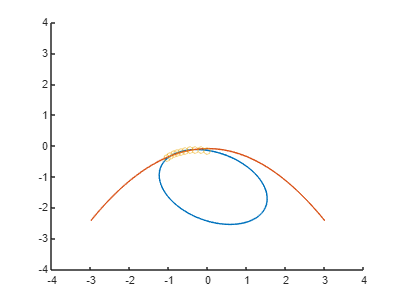

A = [y.^2; x.*y; x; y; x.^0]';
B = (x.^2)';
a = A\B;

A = [y; y.^0]';
b = A\B;

syms X Y
clf; hold on;
fimplicit(-X^2+a(1)*Y^2+a(2)*X*Y+a(3)*X+a(4)*Y+a(5) , [-4 4 -4 4])
fimplicit(-X^2+b(1)*Y+b(2) , [-3 3 -3 1])
scatter(x,y)
hold off;

ellf = @(x,y) -x.^2+a(1).*y.^2+a(2).*x.*y+a(3).*x+a(4).*y+a(5);
parf = @(x,y) -x.^2+b(1).*y+b(2);

ellipse_error = max(abs(ellf(x,y)))

ellipse_error = 6.8002e-04

parabolic_error = max(abs(parf(x,y)))

parabolic_error = 0.2229

Modelul eliptic e mai probabil